# SINDy: comparing diffferent optimizers / regularization

- **STLS**: sequentially thresholding least squares

- **LASSO** 

- **Elastic Net** 

## Generate Data

addpath(genpath(pwd))

param = [10; 28; 8/3]; % Lorenz system parameters (chaotic)
n = 3; % number of states
x0 = [-8; 8; 27];  % Initial condition
dt = 0.001; % time step
tFinal = 20; % final time
tspan = dt:dt:tFinal;
options = odeset('RelTol',1e-12,'AbsTol',1e-12*ones(1,3));
[t,x]=ode45(@(t,x) lorenz(t,x,param),tspan,x0,options);


% Add Gaussian white noise
rng(1)
sig = 0; % noise level
sig = 0.01; % noise level
x = x + sig*std(x(:))*randn(size(x));


% Compute Derivative: finite difference
dx = (1/(12*dt))*(-x(5:end,:)+8*x(4:end-1,:)-8*x(2:end-3,:)+x(1:end-4,:)); % fourth order central difference
x = x(3:end-2,:); % cut tails
t = t(3:end-2,:);


% Pool Data (i.e., build library of nonlinear time series)
polyorder = 3; % polynomials up to order 3
Theta = poolData(x,n,polyorder);


## Lasso

for i = 1:n
    [XL1 FitInfo] = lasso(Theta,dx(:,i),'CV',10);
    % lassoPlot(XL1,FitInfo,'PlotType','CV')
    % lassoPlot(XL1,FitInfo,'PlotType','Lambda')
    
    XiL = XL1(:,FitInfo.Index1SE);
    xL1DeBiased = Theta(:,abs(XiL)>0)\dx(:,i);
    XiL(abs(XiL)>0) = xL1DeBiased;
    XiLASSO(:,i) = XiL;
end

disp('LASSO')

LASSO


disp(poolDataLIST({'x','y','z'},XiLASSO,n,polyorder)) % display LASSO model

    {0×0 char}    {'xdot'   }    {'ydot'   }    {'zdot'   }
    {'1'     }    {[      0]}    {[      0]}    {[      0]}
    {'x'     }    {[      0]}    {[      0]}    {[      0]}
    {'y'     }    {[ 7.8693]}    {[ 8.5680]}    {[      0]}
    {'z'     }    {[      0]}    {[      0]}    {[-2.6636]}
    {'xx'    }    {[      0]}    {[      0]}    {[      0]}
    {'xy'    }    {[      0]}    {[      0]}    {[ 0.9955]}
    {'xz'    }    {[-0.4790]}    {[      0]}    {[      0]}
    {'yy'    }    {[      0]}    {[      0]}    {[ 0.0028]}
    {'yz'    }    {[      0]}    {[      0]}    {[      0]}
    {'zz'    }    {[      0]}    {[      0]}    {[      0]}
    {'xxx'   }    {[      0]}    {[-0.0267]}    {[      0]}
    {'xxy'   }    {[ 0.0146]}    {[      0]}    {[      0]}
    {'xxz'   }    {[      0]}    {[      0]}    {[      0]}
    {'xyy'   }    {[      0]}    {[      0]}    {[      0]}
    {'xyz'   }    {[      0]}    {[      0]}    {[      0]}
    {'xzz'   }    {[ 0.0055]}    {[-0.00

## Elastic Net

for i = 1:n
    [XEN FitInfo] = lasso(Theta,dx(:,i),'CV',10,'Alpha',0.25);

    XiEN = XEN(:,FitInfo.Index1SE);
    XiENDeBiased = Theta(:,abs(XiEN)>0)\dx(:,i);
    XiEN(abs(XiEN)>0) = XiENDeBiased;
    XiElasticNet(:,i) = XiEN;
end

disp('Elastic Net')

Elastic Net


disp(poolDataLIST({'x','y','z'},XiElasticNet,n,polyorder)) % display LASSO model

    {0×0 char}    {'xdot'       }    {'ydot'       }    {'zdot'       }
    {'1'     }    {[          0]}    {[          0]}    {[          0]}
    {'x'     }    {[   -10.7461]}    {[    25.2664]}    {[          0]}
    {'y'     }    {[    10.3943]}    {[     0.5790]}    {[          0]}
    {'z'     }    {[    -0.1182]}    {[    -0.0561]}    {[    -2.6167]}
    {'xx'    }    {[     0.0456]}    {[          0]}    {[    -0.0401]}
    {'xy'    }    {[    -0.0919]}    {[    -0.0060]}    {[     1.0190]}
    {'xz'    }    {[     0.1649]}    {[    -0.8738]}    {[          0]}
    {'yy'    }    {[     0.0298]}    {[          0]}    {[     0.0042]}
    {'yz'    }    {[    -0.0745]}    {[    -0.0832]}    {[          0]}
    {'zz'    }    {[     0.0163]}    {[     0.0064]}    {[    -0.0081]}
    {'xxx'   }    {[     0.0223]}    {[    -0.0042]}    {[          0]}
    {'xxy'   }    {[    -0.0174]}    {[    -0.0022]}    {[          0]}
    {'xxz'   }    {[     0.0012]}    {[ 4.3615e-04]}    {[-5.458

## STLS

% sequentially thresholded least squares
lambda = 0.025;      % lambda is our sparsification knob.
Xi = sparsifyDynamics(Theta,dx,lambda,n); % identify model coefficients
disp('STLS')

STLS


disp(poolDataLIST({'x','y','z'},Xi,n,polyorder)) % display SINDy model

    {0×0 char}    {'xdot'   }    {'ydot'   }    {'zdot'   }
    {'1'     }    {[      0]}    {[      0]}    {[      0]}
    {'x'     }    {[-9.9810]}    {[27.8203]}    {[      0]}
    {'y'     }    {[ 9.9855]}    {[-0.9457]}    {[      0]}
    {'z'     }    {[      0]}    {[      0]}    {[-2.6649]}
    {'xx'    }    {[      0]}    {[      0]}    {[      0]}
    {'xy'    }    {[      0]}    {[      0]}    {[ 0.9992]}
    {'xz'    }    {[      0]}    {[-0.9958]}    {[      0]}
    {'yy'    }    {[      0]}    {[      0]}    {[      0]}
    {'yz'    }    {[      0]}    {[      0]}    {[      0]}
    {'zz'    }    {[      0]}    {[      0]}    {[      0]}
    {'xxx'   }    {[      0]}    {[      0]}    {[      0]}
    {'xxy'   }    {[      0]}    {[      0]}    {[      0]}
    {'xxz'   }    {[      0]}    {[      0]}    {[      0]}
    {'xyy'   }    {[      0]}    {[      0]}    {[      0]}
    {'xyz'   }    {[      0]}    {[      0]}    {[      0]}
    {'xzz'   }    {[      0]}    {[     

## Compare model prediction

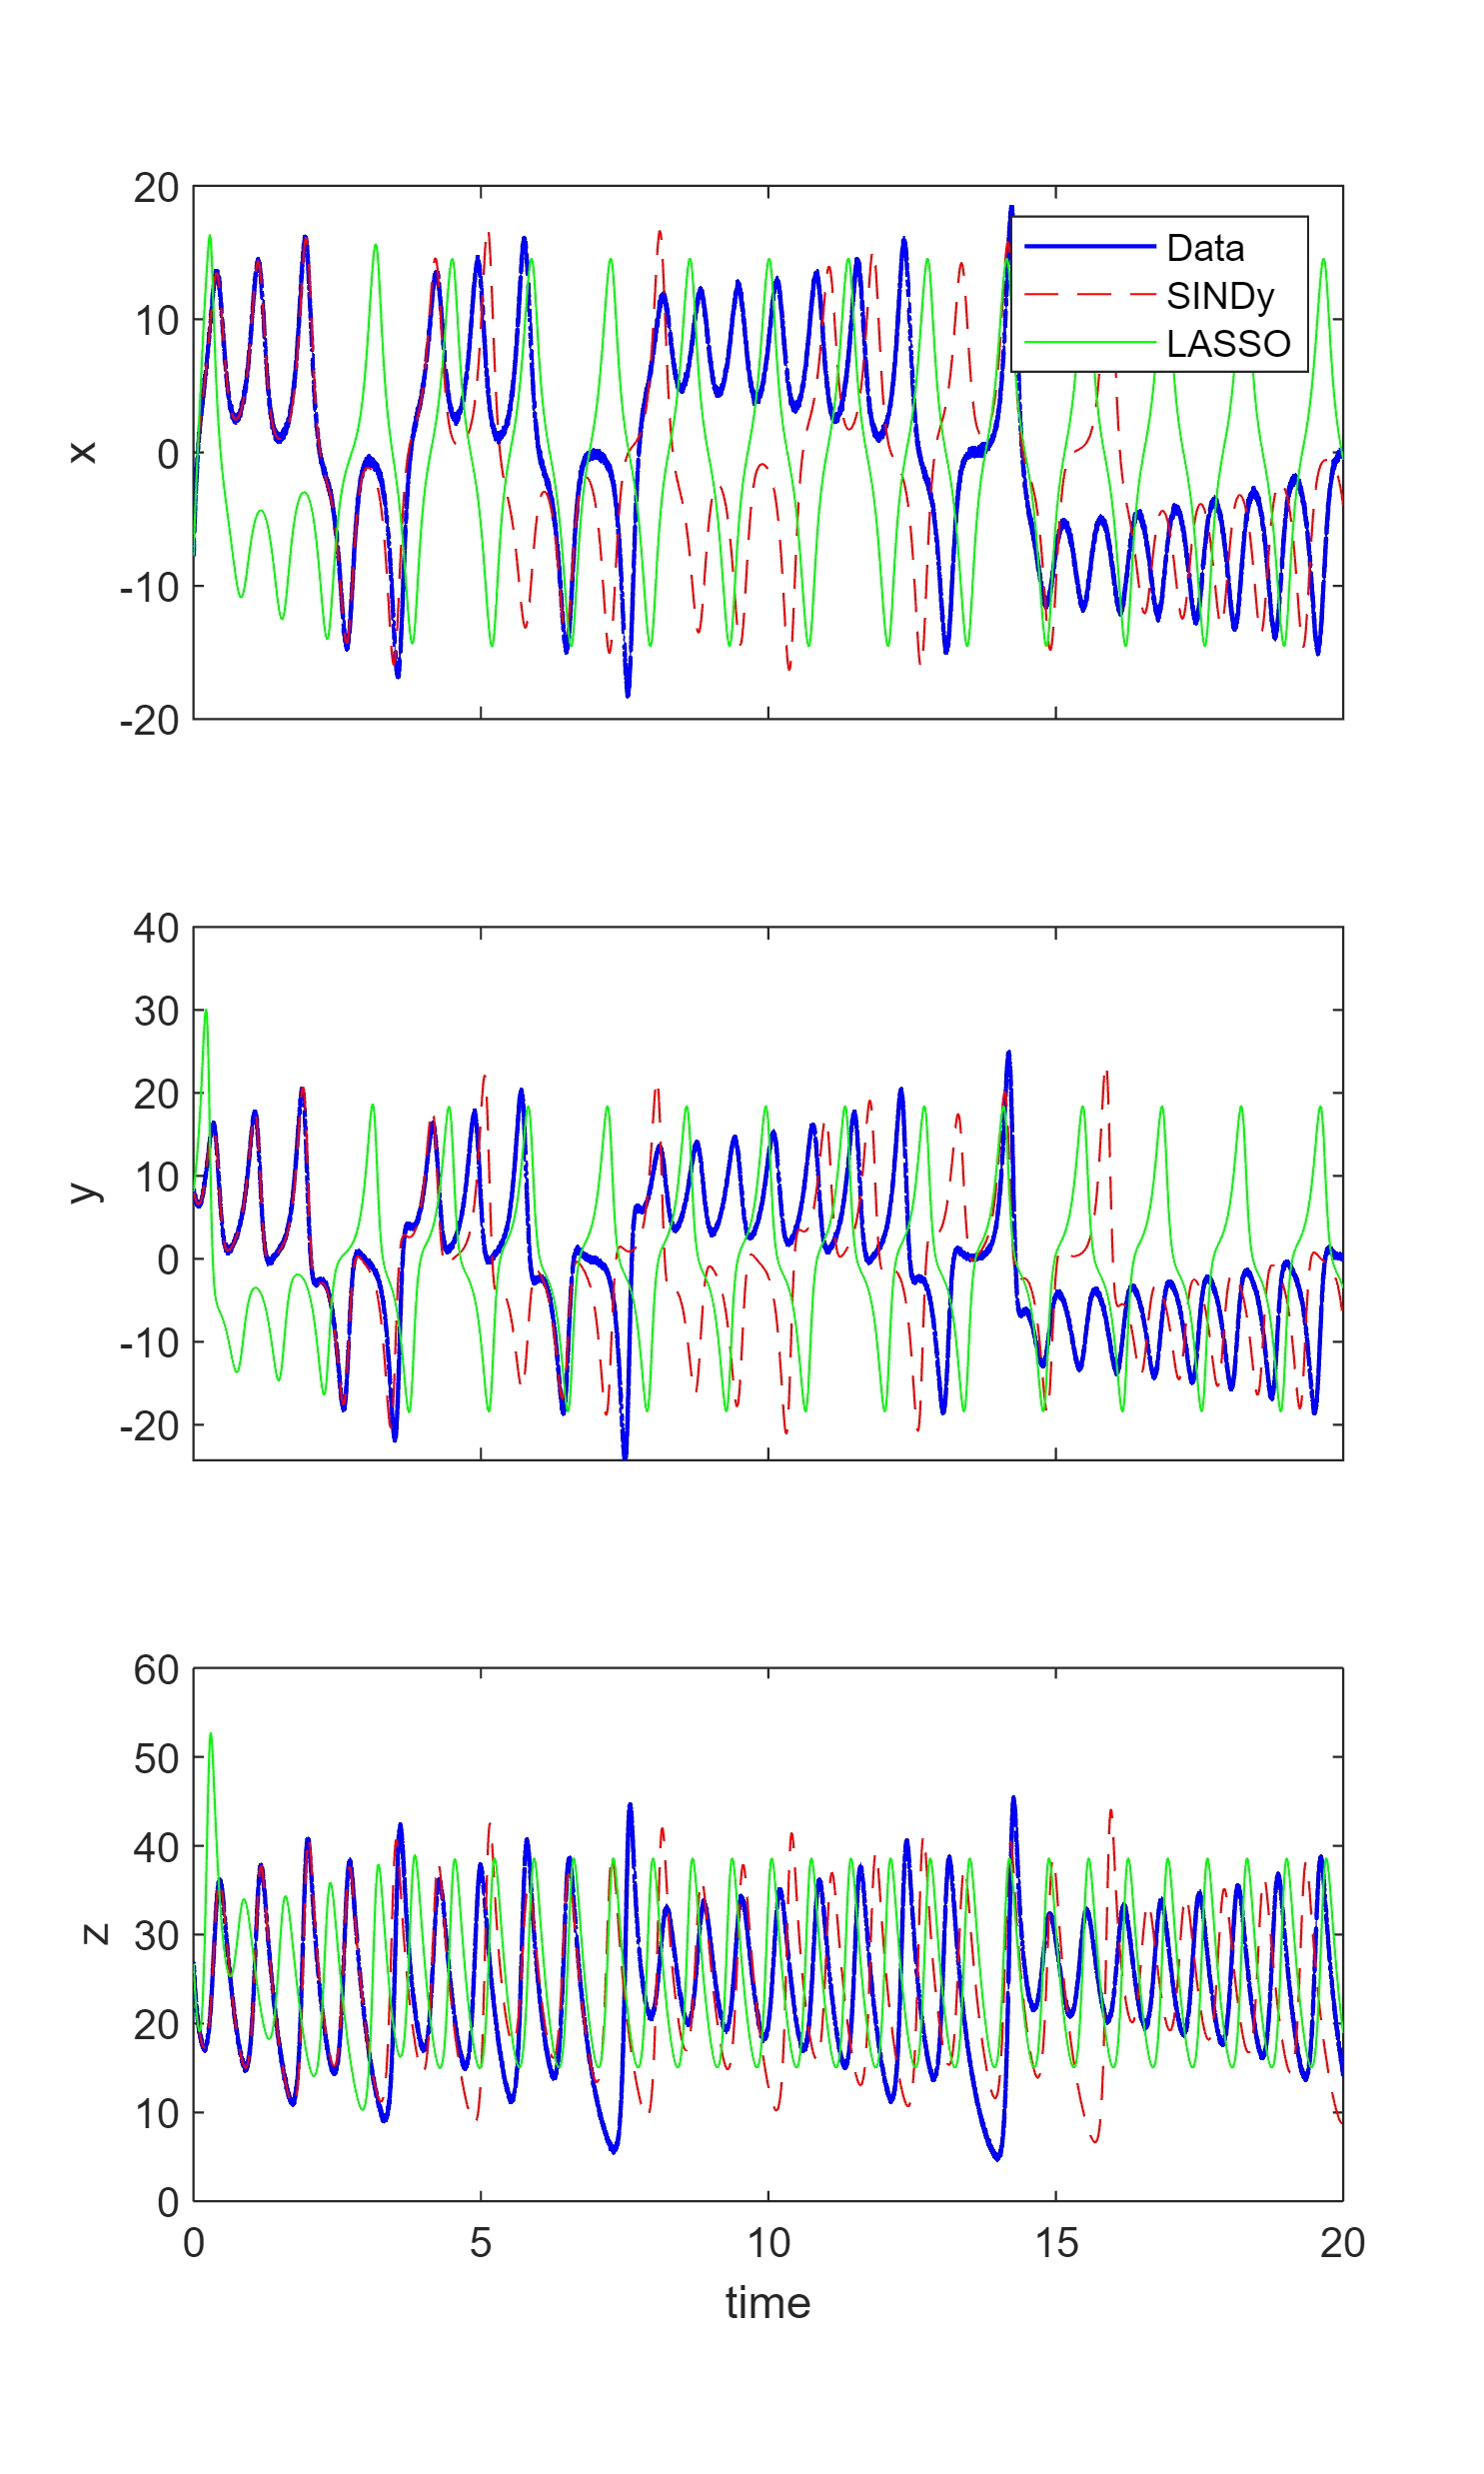

paramSINDy.Xi = Xi;
paramSINDy.polyorder = polyorder;
paramLASSO.Xi = XiLASSO;
paramLASSO.polyorder = polyorder;
paramEN.Xi = XiElasticNet;
paramEN.polyorder = polyorder;
[tSINDy,xSINDy]=ode45(@(t,x) SINDyODE(t,x,paramSINDy),tspan,x0,options);
[tLASSO,xLASSO]=ode45(@(t,x) SINDyODE(t,x,paramLASSO),tspan,x0,options);
[tEN,xEN]=ode45(@(t,x) SINDyODE(t,x,paramEN),tspan,x0,options);

legend = {'Data','SINDy','LASSO'};
plotSINDyLASSO(t,x,tSINDy(3:end-2,:),xSINDy(3:end-2,:),tLASSO(3:end-2,:),xLASSO(3:end-2,:),legend)

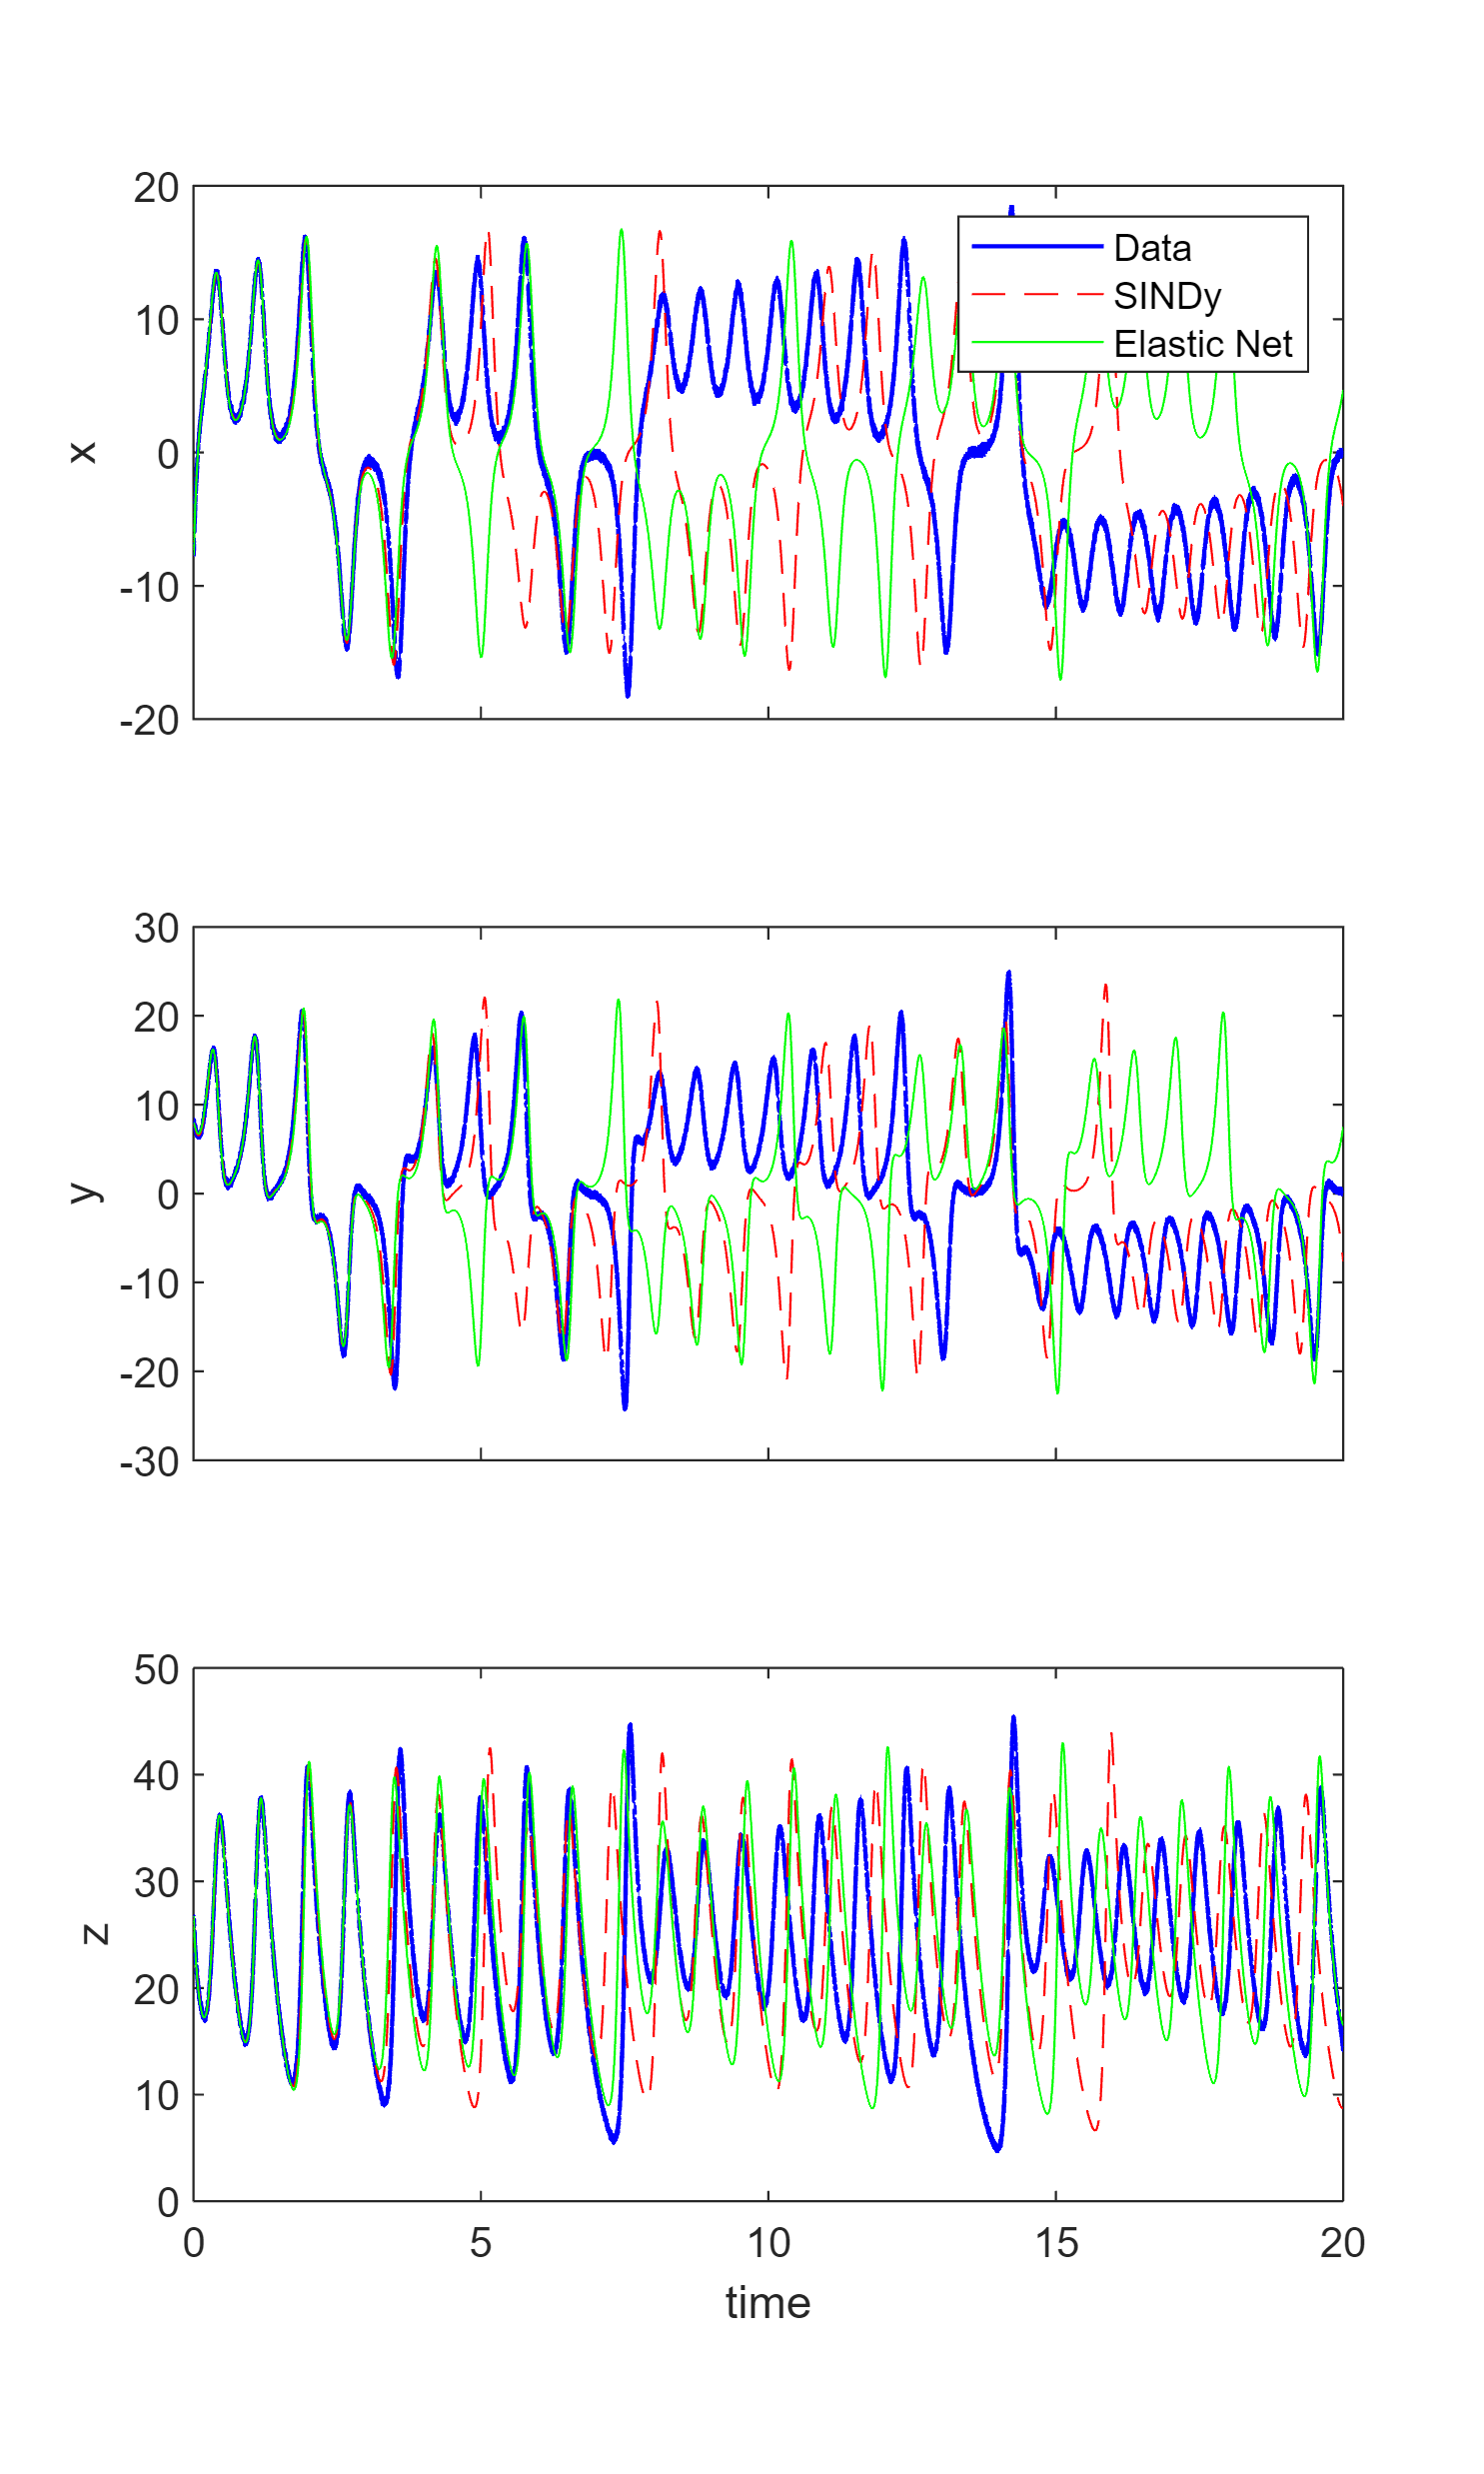


legend = {'Data','SINDy','Elastic Net'};
plotSINDyLASSO(t,x,tSINDy(3:end-2,:),xSINDy(3:end-2,:),tEN(3:end-2,:),xEN(3:end-2,:),legend)